% Time vector for input rf volt and drift
t1 = 0:0.00001:0.008;   

% RF characteristics
A1 = 1;                % Amplitude 1 
f1 = 1 / 0.002;         % Frequency: 1 cycle in 0.002 sec
omega1 = 2 * pi * f1;

% drift characteristics
A2 = 0.2;              % Amplitude 0.02
f2 = 1 / 0.008;         % Frequency: 1 cycle in 0.008 sec
omega2 = 2 * pi * f2;

% modulating rf voltag
Vin = A1 * sin(omega1 * t1);

% drit voltage
Vdrift = A2 * sin(omega2 * t1);

%Powerbytwo=0.2 assuming power =0.4W
A = (0.2+0.2*sin((pi*Vin)/2 +Vdrift))

A =     0.2000    0.2102    0.2203    0.2304    0.2404    0.2502    0.2598    0.2693    0.2785    0.2874    0.2961    0.3044    0.3124    0.3201    0.3274    0.3344    0.3409    0.3471    0.3528    0.3582    0.3632    0.3678    0.3720    0.3759    0.3794    0.3825    0.3853    0.3878    0.3900    0.3920    0.3936    0.3950    0.3962    0.3972    0.3980    0.3986    0.3991    0.3995    0.3997    0.3999    0.4000    0.4000    0.4000    0.3999    0.3998    0.3998    0.3997    0.3996    0.3995    0.3994


B = (0.2-0.2*sin((pi*Vin)/2 +Vdrift))

B =     0.2000    0.1898    0.1797    0.1696    0.1596    0.1498    0.1402    0.1307    0.1215    0.1126    0.1039    0.0956    0.0876    0.0799    0.0726    0.0656    0.0591    0.0529    0.0472    0.0418    0.0368    0.0322    0.0280    0.0241    0.0206    0.0175    0.0147    0.0122    0.0100    0.0080    0.0064    0.0050    0.0038    0.0028    0.0020    0.0014    0.0009    0.0005    0.0003    0.0001    0.0000    0.0000    0.0000    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0006


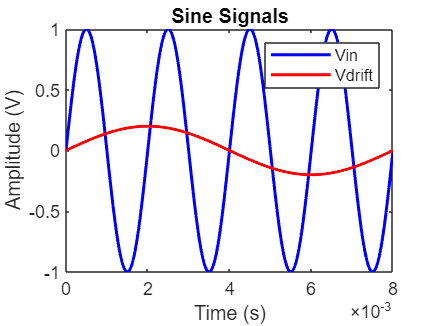


% Plotting the signals
plot(t1, Vin, 'b', 'LineWidth', 1.5);hold on;
plot(t1, Vdrift, 'r', 'LineWidth', 1.5);hold off;
title('Sine Signals');xlabel('Time (s)');ylabel('Amplitude (V)');legend('Vin', 'Vdrift');

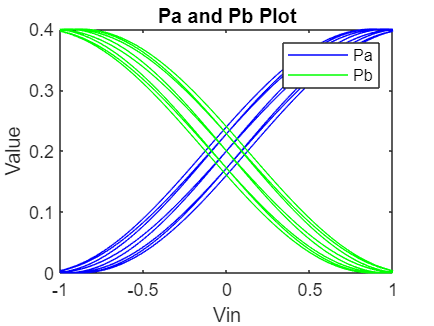


% Plot A and B
plot(Vin, A, 'b', 'LineWidth', 0.4);hold on;
plot(Vin, B, 'g', 'LineWidth', 0.4);hold off;
title('Pa and Pb Plot');xlabel('Vin');ylabel('Value');legend('Pa', 'Pb');


% Define the equations as a function
equations = @(x, A, B) [0.2 + 0.2*sin((pi/2)*x(1) + x(2)) - A; 0.2 - 0.2*sin((pi/2)*x(1) + x(2)) - B];

% initial guesses for Vin and Drift
initialGuess = [0;0];  

% Array of values for A and B
A_values = A;
B_values = B;

% Initialize arrays to store Vin and Vdrift values
Vin_values = zeros(801, 1);
Drift_values = zeros(801, 1);

% Run the loop for different values of A and B
for i = 1:801
    % Retrieve values for A and B from the arrays
    A = A_values(i);
    B = B_values(i);
    
    lb=[-1;-0.2]; %lowerbound
    ub=[1;0.2]; %upperbound
    % solve the system using lsqnonlin
    solution = lsqnonlin(@(x) equations(x, A, B), initialGuess, lb, ub);
    
    % Extract the values of V and D from the solution
    Vin_values(i) = solution(1);
    Drift_values(i) = solution(2);
end


Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<


% Display the results
disp('Vin and Drift values for different combinations of A and B:');

Vin and Drift values for different combinations of A and B:


disp('---');

---


for i = 1:801
   disp(['Combination ' num2str(i) ': Vin = ' num2str(Vin_values(i)) ', Drift = ' num2str(Drift_values(i))]);
end

Combination 1: Vin = 0, Drift = 0
Combination 2: Vin = 0.028749, Drift = 0.0057499
Combination 3: Vin = 0.057473, Drift = 0.011495
Combination 4: Vin = 0.08614, Drift = 0.017228
Combination 5: Vin = 0.11473, Drift = 0.022945
Combination 6: Vin = 0.1432, Drift = 0.02864
Combination 7: Vin = 0.17154, Drift = 0.034307
Combination 8: Vin = 0.19971, Drift = 0.039941
Combination 9: Vin = 0.22769, Drift = 0.045539
Combination 10: Vin = 0.25546, Drift = 0.051092
Combination 11: Vin = 0.28298, Drift = 0.056595
Combination 12: Vin = 0.31023, Drift = 0.062045
Combination 13: Vin = 0.33718, Drift = 0.067435
Combination 14: Vin = 0.3638, Drift = 0.072761
Combination 15: Vin = 0.39008, Drift = 0.078016
Combination 16: Vin = 0.41598, Drift = 0.083196
Combination 17: Vin = 0.4415, Drift = 0.0883
Combination 18: Vin = 0.46658, Drift = 0.093317
Combination 19: Vin = 0.49122, Drift = 0.098244
Combination 20: Vin = 0.51539, Drift = 0.10308
Combination 21: Vin = 0.53907, Drift = 0.10781
Combination 22: Vin

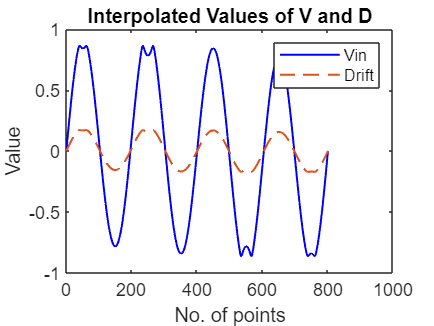


% Interpolate the values of V and D
t_interp = linspace(1, 801, 801);  % Time points for interpolation
V_interp = interp1(1:801, Vin_values, t_interp, 'spline');  % Interpolated values of V
D_interp = interp1(1:801, Drift_values, t_interp, 'spline');  % Interpolated values of D

% Plot the graph
figure;
plot(t_interp, V_interp, 'b', 'LineWidth', 1);hold on;
plot(t_interp, D_interp,'--', 'LineWidth', 1);hold off;
xlabel('No. of points');ylabel('Value');legend('Vin', 'Drift');title('Interpolated Values of V and D');


% Display the results
disp('Interpolated values of Vin and Drift:');

Interpolated values of Vin and Drift:


disp(['Time points: ' num2str(t_interp)]);

Time points: 1    2    3    4    5    6    7    8    9   10   11   12   13   14   15   16   17   18   19   20   21   22   23   24   25   26   27   28   29   30   31   32   33   34   35   36   37   38   39   40   41   42   43   44   45   46   47   48   49   50   51   52   53   54   55   56   57   58   59   60   61   62   63   64   65   66   67   68   69   70   71   72   73   74   75   76   77   78   79   80   81   82   83   84   85   86   87   88   89   90   91   92   93   94   95   96   97   98   99  100  101  102  103  104  105  106  107  108  109  110  111  112  113  114  115  116  117  118  119  120  121  122  123  124  125  126  127  128  129  130  131  132  133  134  135  136  137  138  139  140  141  142  143  144  145  146  147  148  149  150  151  152  153  154  155  156  157  158  159  160  161  162  163  164  165  166  167  168  169  170  171  172  173  174  175  176  177  178  179  180  181  182  183  184  185  186  187  188  189  190  191  192  193  194  195  196  197  198 

disp(['Vin: ' num2str(V_interp)]);

Vin: 0    0.028749    0.057473     0.08614     0.11473      0.1432     0.17154     0.19971     0.22769     0.25546     0.28298     0.31023     0.33718      0.3638     0.39008     0.41598      0.4415     0.46658     0.49122     0.51539     0.53907     0.56222     0.58484     0.60688      0.6284     0.64928     0.66954     0.68916     0.70811     0.72636     0.74384     0.76046     0.77705     0.79243     0.80698     0.82053     0.83279     0.84333     0.85169     0.85752     0.86076     0.86167     0.86072     0.85848     0.85551     0.85227      0.8491     0.84627     0.84394     0.84223      0.8412     0.84088      0.8413     0.84242     0.84422     0.84661     0.84949     0.85267     0.85589     0.85878     0.86089     0.86167     0.86055      0.8571     0.85108     0.84261     0.83202     0.81979     0.80631     0.79188     0.77665     0.76025     0.74384      0.7266     0.70863     0.68999     0.67071     0.65084     0.63037     0.60931     0.58777      0.5657     0.54312     0.520

disp(['Drift: ' num2str(D_interp)]);

Drift: 0   0.0057499    0.011495    0.017228    0.022945     0.02864    0.034307    0.039941    0.045539    0.051092    0.056595    0.062045    0.067435    0.072761    0.078016    0.083196      0.0883    0.093317    0.098244     0.10308     0.10781     0.11244     0.11697     0.12138     0.12568     0.12986     0.13391     0.13783     0.14162     0.14527     0.14877     0.15209     0.15541     0.15849      0.1614     0.16411     0.16656     0.16867     0.17034      0.1715     0.17215     0.17233     0.17214      0.1717      0.1711     0.17045     0.16982     0.16925     0.16879     0.16845     0.16824     0.16818     0.16826     0.16848     0.16884     0.16932      0.1699     0.17053     0.17118     0.17176     0.17218     0.17233     0.17211     0.17142     0.17022     0.16852      0.1664     0.16396     0.16126     0.15838     0.15533     0.15205     0.14877     0.14532     0.14173       0.138     0.13414     0.13017     0.12607     0.12186     0.11755     0.11314     0.10862     0.1